
clc
clear all
%% Import data from text file
% Script for importing data from the following text file:
%
%    filename: C:\Temp\xkleme13\MKS23\cv06-tempsens\ntc.csv
%
% Auto-generated by MATLAB on 02-Nov-2023 14:57:34

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Temp", "Resitance"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
ntc = readtable("C:\Temp\xkleme13\MKS23\cv06-tempsens\ntc.csv", opts);


%% Clear temporary variables
clear opts

%% Convert to output type
t = ntc.Temp;
r = ntc.Resitance;

%% Clear temporary variables
clear opts tbl

%% Processing
ad = (r ./ (r + 10)) * 2^10;
p = polyfit(ad, t, 10);

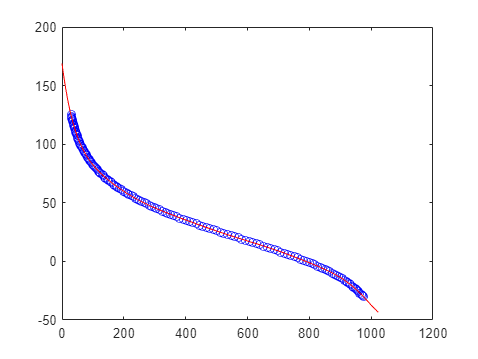


ad2 = 0:1023;
t2 = round(polyval(p, ad2), 1);

figure;
plot(ad, t, 'bo');
hold on;
plot(ad2, t2, 'r');



% Save the temperature values in the specified format
dlmwrite('data.dlm', t2*10, ',');

